288chドップラー使いづらいのでMatlab書き直し

・ダメなチャンネル抜いたりしてきれいに再構成

clear all
close all
tmax=100

tmax = 100

EM_max=1.e8

EM_max = 100000000

lambda0=480.6%656.3%471.3%656.3%480.6%587.562%486.133%656.3%486.133%468.57%486.133%nm

lambda0 = 480.6000

mass=39.95%4.%12.01%39.95%1.

mass = 39.9500

resolution=-1.420387e-12*lambda0^3 - 2.156031e-09*lambda0^2 + 1.250038e-06*lambda0 + 3.830769e-03%0.0037714% -0.000000000001420387*lambda0^3 - 0.000000002156031*lambda0^2 + 0.000001250038*lambda0 + 0.003830769

resolution = 0.0038


z=readmatrix("z.txt")*1e-3;
%[file,path] = uigetfile('*.asc')
%filename=fullfile(path,file)
filename='I:\Doppler\288CH\20211223\shot8_PF39_TF28_EF150_delay470_w.asc';
[d,delimiterOut]=importdata(filename);d=d(:,2:end)';
%[file,path] = uigetfile('*.asc')
%filenamebg=fullfile(path,file)
filenamebg='I:\Doppler\288CH\20211224\bg.asc';
bg=importdata(filenamebg);bg=bg(:,2:end)';d=d-bg;
calib=readmatrix("Ar.calibration.0604.txt");
%calib=readmatrix("Ar_calibration_20211223-24.txt")
CH=squeeze(calib(:,1));
Center=squeeze(calib(:,2))-2;
Smile=squeeze(calib(:,3))-30;
relative=squeeze(calib(:,5));
instru=squeeze(calib(:,6));


separation=find(mod(CH-1,16)==1)-1 ; separation(4)=separation(4)+1;
%なんかあわない

p=readmatrix("r.txt")*1.e-3;p=p(:,4)

p =     0.0770
    0.0905
    0.1041
    0.1177
    0.1314
    0.1450
    0.1586
    0.1720
    0.1852
    0.1982


zall=repmat(z,1,16)';
pall=repmat([p,flip(p)],1,9);
edge=0.3;
Ti_instru=1.69e8.*mass.*(2.*resolution.*instru.*sqrt(2.*log(2.))/lambda0).^2;

lambda=zeros([1024 numel(CH)]);
x=(1:1024);
for i=1:numel(CH) 
lambda(:,i)=(x-Smile(i))*resolution+lambda0;%+0.13;
end
spectra=zeros([1024 numel(CH)]);
figure('Visible','on')
subplot('Position',[0.1,0.4,0.85,0.55])
interval=7;
contourf(x,x,d,30,'LineStyle','none')
%caxis([min(d,[],'all') (max(d,[],'all')-min(d,[],'all'))*0.1+min(d,[],'all')])
caxis([min(d,[],'all') max(d,[],'all')])
ylim([min(Center)-interval-5 max(Center)+interval+5])
axis tight
hold on
for i=1:numel(CH)
plot(Smile(i)+[-40,40],Center(i)*[1,1],'r')
plot(Smile(i)*[1.,1.],Center(i)+[-7,7],'g')
plot(Smile(i)+[-40,40],Center(i)*[1,1]+interval,':y')
plot(Smile(i)+[-40,40],Center(i)*[1,1]-interval,':b')
end
hold off

 xr=[410,540]

xr =    410   540


 lambdaA=(x-(xr(1)+xr(2))/2.).*resolution+lambda0 ;
 lambdaB=lambdaA 

lambdaB =   478.8102  478.8140  478.8178  478.8216  478.8253  478.8291  478.8329  478.8367  478.8404  478.8442  478.8480  478.8518  478.8555  478.8593  478.8631  478.8669  478.8707  478.8744  478.8782  478.8820  478.8858  478.8895  478.8933  478.8971  478.9009  478.9046  478.9084  478.9122  478.9160  478.9197  478.9235  478.9273  478.9311  478.9348  478.9386  478.9424  478.9462  478.9499  478.9537  478.9575  478.9613  478.9650  478.9688  478.9726  478.9764  478.9802  478.9839  478.9877  478.9915  478.9953


 lambdaA=lambdaA(xr(1):xr(2));
ybin=sum(d,1);
subplot('Position',[0.1,0.05,0.85,0.35])
plot(x,ybin,'*')
axis tight
hold on
%gaussEqn='a0*exp(-((x-a1)/a2)^2)+a3+a4*x';
f=fit(x(xr(1):xr(2))',ybin(xr(1):xr(2))','gauss1')

f =      一般モデル Gauss1:
     f(x) =  a1*exp(-((x-b1)/c1)^2)
     係数 (95% の信頼限界):
       a1 =   1.825e+07  (1.782e+07, 1.867e+07)
       b1 =       500.6  (500.4, 500.8)
       c1 =       10.83  (10.54, 11.12)

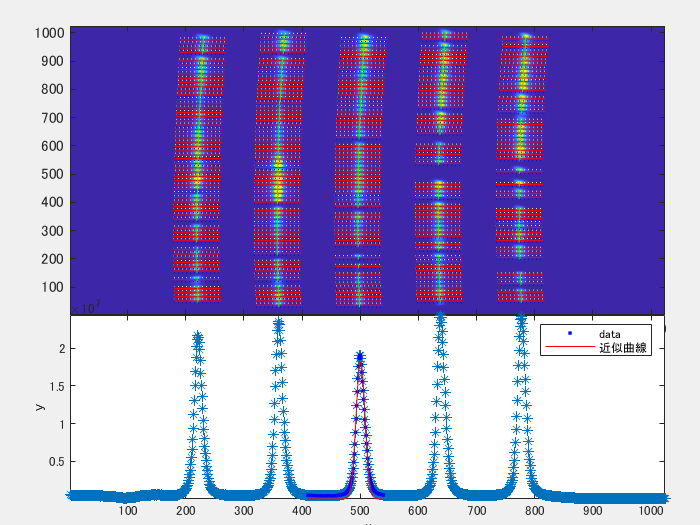

plot(f,x(xr(1):xr(2)),ybin(xr(1):xr(2)))

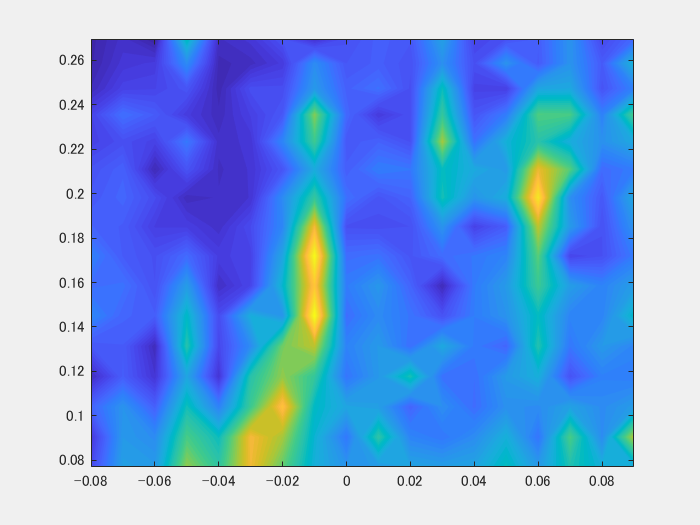


% A=[coeff[0],200,coeff[2],coeff[0],350,coeff[2],coeff[0],500,coeff[2],coeff[0],650,coeff[2],coeff[0],800,coeff[2],coeff[3],0,0]
% fita=A*0.+1.
% %stop
% %**************************
% %*Line-integrated analysis*
% %**************************
% 
 passive.Ti=CH*0.;
 passive.Timax=CH*0.;
 passive.Timin=CH*0.;
 passive.Em=CH*0.; 

%figure('Visible','on')
for i=1:numel(CH)
%     if ismember(i,separation)
%         figure('Name',num2str(round(CH(i)/16+2)),'Visible','on')
%     end
%    subplot(4,4,mod(CH(i)-1,16)+1)
    spectra(:,i)=sum(d(Center(i)-interval:Center(i)+interval,:),1)*relative(i)    ;    %各チャンネルのガウシアン信号を積分
    input=squeeze(spectra(:,i))-median(spectra(:,i)) ;
    c=fit(x(1,round(Smile(i))-75:round(Smile(i))+75)',input(round(Smile(i))-75:round(Smile(i))+75,1),'gauss1') ;  %passive.Ti(i)=1.69e8*mass*(2.*resolution*(coeff[2])*sqrt(2.*alog(2.))/lambda0)^2-Ti_instru(i)
    conf=confint(c);
    passive.Ti(i)=1.69e8*mass*(2.*resolution*c.c1*sqrt(2.*log(2.))/lambda0)^2-Ti_instru(i);
    passive.Timax(i)=1.69e8*mass*(2.*resolution*conf(2,3)*sqrt(2.*log(2.))/lambda0)^2-Ti_instru(i);
    passive.Timin(i)=1.69e8*mass*(2.*resolution*conf(1,3)*sqrt(2.*log(2.))/lambda0)^2-Ti_instru(i);
%    plot(c,x(1,round(Smile(i))-75:round(Smile(i))+75),input(round(Smile(i))-75:round(Smile(i))+75,1))
    passive.Em(i)=resolution*sum(input(round(Smile(i))-75:round(Smile(i))+75));
%    spectra(:,i)=input;
end
clear conf c input 


figure('Visible','on')
plot(CH,passive.Ti,'ro')
hold on
plot([CH CH]',[passive.Timin passive.Timax]','b-_')
xline(CH(separation),':')
%ar1=area(CH,[passive.Timax, passive.Timin-passive.Timax])
%set(ar1(1),'FaceColor','None','LineStyle','None')
%set(ar1(2),'FaceColor',[0 0.2 1],'FaceAlpha',0.2,'LineStyle','None')
% errplot,CH,passive.Timin,


figure('Visible','on')
 Ti2D=zeros([numel(p),numel(z)]);
 Em2D=zeros([numel(p),numel(z)]);
 for i=1:size(zall,2)
 Ti2D(:,i)=pchip(pall(CH(zall(CH)==zall(1,i))),passive.Ti(zall(CH)==zall(1,i)),sort(pall(:,i)));
 Em2D(:,i)=pchip(pall(CH(zall(CH)==zall(1,i))),passive.Em(zall(CH)==zall(1,i)),sort(pall(:,i)));
 plot(pall(CH(zall(CH)==zall(1,i))),passive.Em(zall(CH)==zall(1,i)),'o')
 hold on
 plot(sort(pall(:,i)),Em2D(:,i))
 end
 % passiveGrid.zq=zall;
% passiveGrid.rq=pall;

 figure('Visible', 'on')
 contourf(z,p,(Ti2D)/max(Ti2D,[],'all'),60,'LineStyle','none')
 figure('Visible', 'on')
 contourf(z,p,(Em2D)/max(Em2D,[],'all'),60,'LineStyle','none')

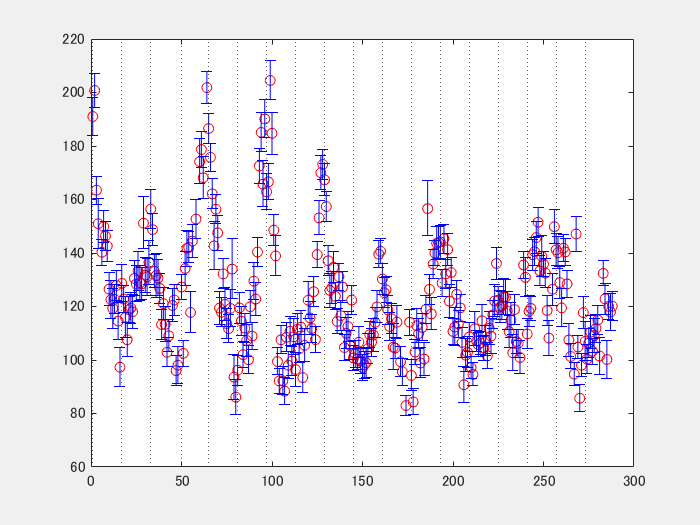

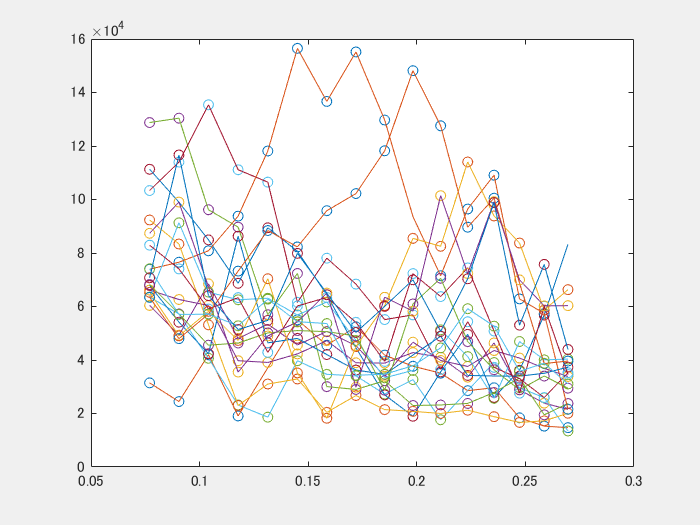

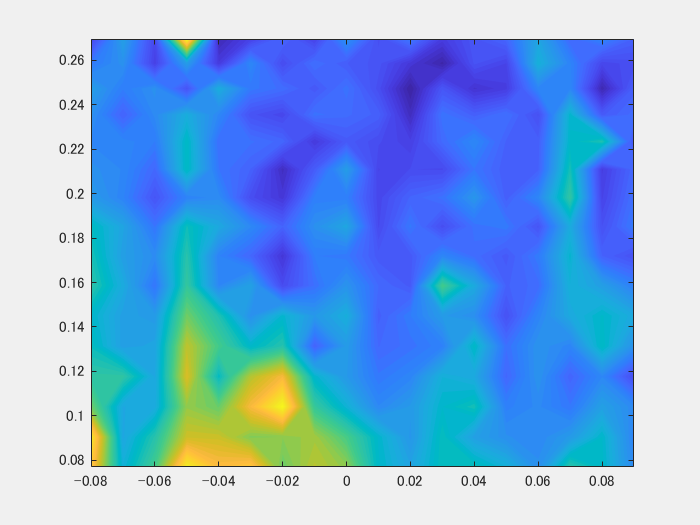


% %******************
% %*Abel-ininversion*
% %******************

num=50;
yy=[1:num]/num*(edge-min(p))+min(p);
spectra_interp=zeros([numel(yy),numel(lambdaA),numel(z)]);
%grid2D=meshgrid(lambdaA,yy);
for i=1:numel(z) 
    [Yin,I]= sort(pall(CH(zall(CH)==zall(1,i))));
    Xin=lambda(:,zall(CH)==zall(1,i));
    Zin=spectra(:,zall(CH)==zall(1,i));
    Yin=[Yin', edge];
    Xin=[Xin(:,I),lambdaB'];
    Zin=[Zin(:,I),zeros(numel(lambdaB),1)];
    result=Trigrid_interpor_for_r_lambda(Zin,Xin,Yin,lambdaA,yy);
spectra_interp(:,:,i)=result.Z;
end
% for j=1:numel(z)
%  for i=1:num  
%    if mod(i, 36)==1 
%        figure('Visible','on')
%    end
%    subplot(6,6,mod(i-1, 36)+1)
%    f=fit(lambdaA',squeeze(spectra_interp(i,:,j))','gauss1');
%    plot(f,lambdaA',squeeze(spectra_interp(i,:,j)'))
%    legend('off')
%  end 
% end

 
 
 spectra_interp=smoothdata(spectra_interp,1,'movmean',num/16);
 spectra_interp=smoothdata(spectra_interp,2,'movmean',5);
 spectra_interp=smoothdata(spectra_interp,3,'movmean',1);
% dy=yy(2)-yy(1);
reconst_int=spectra_interp*0;
[~,dndy,~]=gradient(spectra_interp,1,yy,1);
dy=diff(yy);
for i=1:numel(z)
 for j=1:num 
  for k=j+1:num 
     reconst_int(j,:,i)=reconst_int(j,:,i)-1./pi.*dndy(k,:,i)./sqrt(yy(k).^2-yy(j).^2).*dy(k-1);
  end
 end
end
% reconst_int=smooth(reconst_int,[5,num/16,1])
% 
 emission=zeros([num,numel(z)]);
 Ti.Ti2D=zeros([num,numel(z)]);
 Ti.max=zeros([num,numel(z)]);
 Ti.min=zeros([num,numel(z)]);
 Ti_instru2=Ti_instru*0;
 for i=1:numel(z)
     Ti_instru2(zall(CH)==zall(1,i))=sum(Ti_instru(zall(CH)==zall(1,i)))/sum(zall(CH)==zall(1,i));
 end 
 for i=1:num  
     for j=1:numel(z)
%    if mod(i, 36)==1 
%        figure('Visible','on')
%    end
%   subplot(6,6,mod(i-1, 36)+1)
    input=squeeze(reconst_int(i,:,j));%input(input<=0)=-input(input<=0);
    c=fit(lambdaA',input','gauss1');   
    conf=confint(c);
    Ti.Ti2D(i,j)=1.69e8*mass*(2.*resolution*c.c1*sqrt(2.*log(2.))/lambda0)^2-Ti_instru2(j);
    Ti.max(i,j)=1.69e8*mass*(2.*resolution*conf(2,3)*sqrt(2.*log(2.))/lambda0)^2-Ti_instru2(j);
    Ti.min(i,j)=1.69e8*mass*(2.*resolution*conf(1,3)*sqrt(2.*log(2.))/lambda0)^2-Ti_instru2(j);
    emission(i,j)=resolution*sum(input);
    %checker=(abs(c.b1-lambda0) < 0.3) & (c.a1 > 0 )& (emission(i,j) >= 100)& (abs(Ti.max(i,j)-Ti.min(i,j)) < Ti.Ti2D(i,j))%*float(abs(Ti.max(i,j)-Ti.min(i,j)) lt Ti.Ti2D(i,j)+Ti_instru2[j])%*(emission_local(i,j) gt EM_max*0.1);
%  if checker==false
%      Ti.Ti2D(i,j)=NaN;
%      Ti.max(i,j)=NaN;
%      Ti.min(i,j)=NaN;
%  end
     end 
 end 

% for i=0,num  
% %if i mod 36 eq 0 then window, fix(i/36),xsize=1700,ysize=900
%   for j=0,numel(z)-1  
%   input=squeeze(reconst_int(:,i,j]) %&  if input lt 0 then input[*] = -input[*] %-min(smooth(squeeze(reconst_int(:,i,j]),20))
%   fit = gaussfit(lambdaA,input,coeff,nterms=3,sigma=sigma)
%  % stop
% % plot,lambdaA,input,xst=1,yst=1,title="(R,Z) ="+strcompress(yy(i),/remove_all)+","+strcompress(z[j],/remove_all),charsize=1.5
% % oplot,lambdaA,fit,color=250,thick=2
%   Ti.Ti2D(i,j)=1.69e8*MASS*(2.*coeff[2]*sqrt(2.*alog(2.))/lambda0)^2-Ti_instru2[j]
%   Ti.max(i,j)=1.69e8*MASS*(2.*(abs(coeff[2])+3.*abs(sigma[2]))*sqrt(2.*alog(2.))/lambda0)^2-Ti_instru2[j]
%   Ti.min(i,j)=1.69e8*MASS*(2.*(abs(coeff[2])-3.*abs(sigma[2]))*sqrt(2.*alog(2.))/lambda0)^2-Ti_instru2[j]
%   emission(i,j)=sum(input*resolution)%coeff[0]
%   checker=float(abs(coeff[1]-lambda0) lt 0.3)*(coeff[0] gt 0)*(emission(i,j) gt 100)*float(abs(Ti.max(i,j)-Ti.min(i,j)) lt Ti.Ti2D(i,j))%*float(abs(Ti.max(i,j)-Ti.min(i,j)) lt Ti.Ti2D(i,j)+Ti_instru2[j])%*(emission_local(i,j) gt EM_max*0.1)
%   Ti.Ti2D(i,j)=Ti.Ti2D(i,j)*checker & Ti.max(i,j)=Ti.max(i,j)*checker & Ti.min(i,j)=Ti.min(i,j)*checker
%    end
%  end
% 
% %remove "NAN" grid point
% for i=0,numel(z)-1  
%   for j=0,numel(yy)-1  
%     if finite(Ti.Ti2D[j,i]) ne 1  
%     Ti.Ti2D[j,i]=0.
%     Ti.max[j,i]=0.
%     Ti.min[j,i]=0.
%     print,i,j   
%      end 
%    end
%  end
% 
% 
% start=where((yy gt p[0])) & start=start[0]
% %Ti.Ti2D=Ti.Ti2D*float(emission_local gt 0)
% %Ti.Ti2D=Ti.Ti2D*float(emission_local gt EM_max*0.04)
% %for i=0,numel(z)-1 do Ti.Ti2D(:,i]=Ti.Ti2D(:,i]*float(abs(Ti.max(:,i]-Ti.min(:,i]) lt Ti.Ti2D(:,i]+Ti_instru2(i))
% checker=Ti.Ti2D  >= 0
% for i=start,numel(yy)-2  
%     for j=0,numel(z)-1  
%       if checker(i,j)  
%         Ti.Ti2D(i,j)=sqrt((Ti.Ti2D[i+1,j]+Ti.Ti2D[i-1,j])/2.)
%         Ti.max(i,j)=(Ti.max[i+1,j]+Ti.max[i-1,j])/2.  
%         Ti.min(i,j)=(Ti.min[i+1,j]+Ti.min[i-1,j])/2.        
%        end
%      end  
%  end
% loadct,39
% window,26,ysize=800 & !P.multi=[0,1,2]
% contour,Ti.Ti2D/tmax,yy,z,/fill,nlevels=256,xst=1,yst=1,zst=1,/isotropic,zr=[0,1],xr=[min(p),max(p)]
% loadct,1 &contour,emission/max(emission*0.75),yy,z,/fill,nlevels=256,xst=1,yst=1,zst=1,/isotropic,zr=[0,1],xr=[min(p),max(p)]%max(Em2D)*0.75]
% 
% window,27,ysize=500,xsize=1400
% !P.multi=[0,4,1]
% loadct,39 & contour,transpose(Ti2D),z,p,/fill,nlevels=256,xst=1,yst=1,zst=1,zr=[0,tmax],xtitle="Z[m]",ytitle="R[m]",title="Ti(Projection)"%,/isotropic
% plot,Ti2D(:,0],p,xst=1,yst=1,xr=[0,tmax*2],/nodata,xtitle="Ti [eV]",ytitle="R[m]",title="Ti(Projection)" & for i=0,5 do oplot,Ti2D(:,i],p,color=i*50,psym=-8
% loadct,39 & contour,transpose(Ti.Ti2D),z,yy,/fill,nlevels=256,xst=1,yst=1,zst=1,zr=[0,tmax],xtitle="Z[m]",ytitle="R[m]",title="Ti(Local)",yr=[min(p),max(p)]%,/isotropic
% plot,Ti.Ti2D(:,0],yy,xst=1,yst=1,xr=[0,tmax*2],/nodata,xtitle="Ti [eV",ytitle="R[m]",title="Ti(Local)",yr=[min(p),max(p)] & for i=0,17 do oplot,Ti.Ti2D(:,i],yy,color=i*15,psym=-8
% 
% window,28,xsize=1800,ysize=700 & loadct,5
% !P.multi=[0,4,5]
% for i=0,numel(z)-1  
% contour, reconst_int(:,:,i],lambdaA,YY,/fill,nlevels=32,xst=1,yst=1,zst=1,zr=[0,max(local_spectra)]
% oplot,lambda0*[1,1],[0,1000],linestyle=2,color=125,thick=2
%  end
% 
% %data=MAG_CAO(EF=-150,m_num=4,n_num=4,n_frame=16,dateshot=190605010)
% restore,"\\192.168.1.140\md0\makimitsu\fordoppler2174.sav"
% window,30,xsize=1200,ysize=600 & !P.multi=[0,2,1] & loadct,39
% contour,transpose(Ti.Ti2D)/tmax,z,yy,/fill,nlevels=256,xst=1,yst=1,zst=1,zr=[0,1],/isotropic,xtitle="Z [m]",ytitle="R [m]",title="Ti (Local)",color=255,background=0%yr=[0.15,max(p)],xr=[-0.025,0.025],
% %for i=0,numel(z)-1 do oplot,zeros(numel(p))+Z(i),p,psym=8,color=250
% %contour,data.A[13:28,:,1]/max(abs(data.A[13:28,:,1])),data.b[13:28],data.c,/overplot,nlevels=50,color=0,thick=2.0
% %contour,-data.A[13:28,:,1]/max(abs(data.A[13:28,:,1])),data.b[13:28],data.c,/overplot,nlevels=50,color=0,thick=2.0
% contour,(psi(:,:,12]/max(abs(psi))+1)/2,xout,yout,/overplot,nlevels=100
% loadct,5 & contour,transpose(emission)/max(emission*0.75),z,yy,/fill,nlevels=256,xst=1,yst=1,zst=1,zr=[0,1],/isotropic,xtitle="Z [m]",ytitle="R [m]",title="Emission (Local)",color=255,background=0%,yr=[0.15,max(p)],xr=[-0.025,0.025]
% contour,(psi(:,:,12]/max(abs(psi))+1)/2,xout,yout,/overplot,nlevels=100
% loadct,39%& for i=0,numel(z)-1 do oplot,zeros(numel(p))+Z(i),p,psym=8,color=150
% 
% %contour,data.A[13:28,:,1]/max(abs(data.A[13:28,:,1])),data.b[13:28],data.c,/overplot,nlevels=50,color=0,thick=2.0
% %contour,-data.A[13:28,:,1]/max(abs(data.A[13:28,:,1])),data.b[13:28],data.c,/overplot,nlevels=50,color=0,thick=2.0
% stop
% 
% contour,smooth(Ti.Ti2D,[num/16,2])/tmax,yy,z,/fill,nlevels=256,/isotropic,title="Ti::"+filename,xst=1,yst=1,zst=1,zr=[0,1],xtitle="R [m]",ytitle="Z [m]",xr=[min(p),max(p)],charsize=1.0,color=0,background=16777215L%,color=16777215L
% for i=0,numel(z)-1 do oplot,p,zeros(numel(p))+Z(i),psym=8,color=250
% contour,transpose(data.A[62:143,2:194,10])/max(abs(data.A[62:143,2:194,10])),data.c[2:194],data.b[62:143],/overplot,nlevels=30,color=0,thick=2.0
% contour,-transpose(data.A[62:143,2:194,10])/max(abs(data.A[62:143,2:194,10])),data.c[2:194],data.b[62:143],/overplot,nlevels=30,color=0,thick=2.0
% 
% %stop
% data=mrd_analysis(150.)
% window,31 ,ysize=1000,xsize=700 & !P.multi=0 
% contour,transpose(data.A(:,:,80])/max(abs(data.A(:,:,80])),data.c,data.b,nlevels=30,xst=1,yst=1,zst=1,color=0,xtitle="R [m]",ytitle="Z [m]",thick=2.0,background=16777215L
% contour,-transpose(data.A(:,:,80])/max(abs(data.A(:,:,80])),data.c,data.b,nlevels=30,/overplot,color=0,thick=2.0
% 
% colorbar=[[findgen(256)],[findgen(256)]]
% x=findgen(256)/256*tmax
% y=[0,1]
% window,ysize=400
% contour,colorbar,x,y,/fill,nlevel=256,xst=1,yst=7,zst=1,title="Ti[eV]",position=[0.1,0.85,0.9,0.9],color=0,background=255
% %cb=colorbar(target=smooth(Ti.Ti2D,[num/16,2])/tmax,orientation=0
% %colorbar =[[findgen(255)-127.)/127.],[findgen(255)-127.)/127.]]
% %contour,colorbar,(findgen(255)-127.)/127.,[0,1],/fill,nlevels=32,/noerase,position=[0.1,0.85,0.9,0.9],title="Ti::"+filename,color=white,xst=1,yst=4
% stop
% %
% %stop
% %save,filename=filename+".sav",Ti.Ti2D,yy,z,emission_local
% %kannkeinaityo
% %save,filename=strmid(filename,0,48)+".sav",Ti.Ti2D,yy,z,emission_local
% 


function result=Trigrid_interpor_for_r_lambda(z,x,y,xout,yout)

%Nterms=N_elements(x)*N_elements(y)
Nterms=numel(x);
Xtemp=x' ;Xtemp= Xtemp(:);
Ytemp=repmat(y,1,Nterms/numel(y))'; 
SigTemp=z';SigTemp=SigTemp(:);
[xq,yq]=meshgrid(xout,yout);
A=griddata(Xtemp,Ytemp,SigTemp,xq,yq);
% figure('Visible','on')
% plot(Xtemp,Ytemp,'.');
% hold on
% contourf(xq,yq,A)
% hold off


result=struct('Z',A,'X',xout,'Y',yout);
end
